clear;clc

%% 系统参数
m1 = 10;
m2 = 1.6;
k1 = 34000;
k2 = 100000;
k_m = 5;
k_E = 5;
L = 0.0014;
R_m = 2.1;
c1 = 1;
c2 = 0.1;

%% 状态空间方程建立

A = [0      1       0           0;
    -k1/m1  -c1/m1  k1/m1       c1/m1;
    0       0       0           1;
    k1/m2   c1/m2   -(k1+k2)/m2 -(c1-c2)/m2]

A = 1.0e+04 *

         0    0.0001         0         0
   -0.3400   -0.0000    0.3400    0.0000
         0         0         0    0.0001
    2.1250    0.0001   -8.3750   -0.0001


B = [0 0 0 1/m2]'

B =          0
         0
         0
    0.6250


E = [0      0;
     0      0;
     0      0;
     c2/m2  k2/m2]

E = 1.0e+04 *

         0         0
         0         0
         0         0
    0.0000    6.2500


C = [-k1/m1 -c1/m1   k1/m1       c1/m1;
     k1/m2   c1/m2   -(k1+k2)/m2 -(c1-c2)/m2]

C = 1.0e+04 *

   -0.3400   -0.0000    0.3400    0.0000
    2.1250    0.0001   -8.3750   -0.0001


D = 0

D = 0

system = ss(A,B,C,D);
%%%%% 

## LQR控制



%% LQR增益求解

Q = [1 0   0 0;
      0 1e5 0 0;
      0 0   0 0;
      0 0   0 1e5];
R = 1;
K = lqr(system,Q,R)

K = 1.0e+03 *

   -1.9999    0.2383    1.9999    0.3254


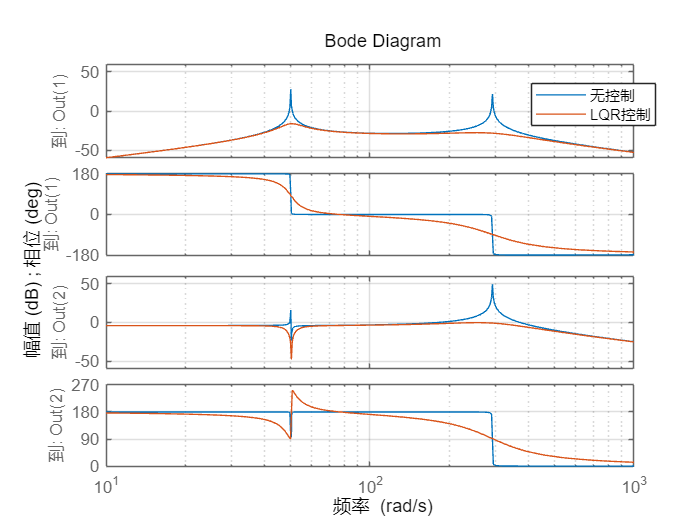

%% 新系统建立
system_LQR = ss(A-B*K,B,C,D);
%% 绘制系统伯德图
figure
bode(system)
hold on
bode(system_LQR)
grid on
h = gcf; % 获取当前图形句柄
% 设置频率范围（以rad/s为单位）
set(h.Children(2:5), 'XLim', [10, 1000]); % 频率范围
% 设置增益范围（以分贝为单位）
set(h.Children(3), 'YLim', [-60, 60]); % 增益范围
set(h.Children(5), 'YLim', [-60, 60]); % 增益范围
legend('无控制', 'LQR控制')
legend("Position", [0.7581,0.7604,0.17857,0.082143])

## 优化伯德图(坐标映射)

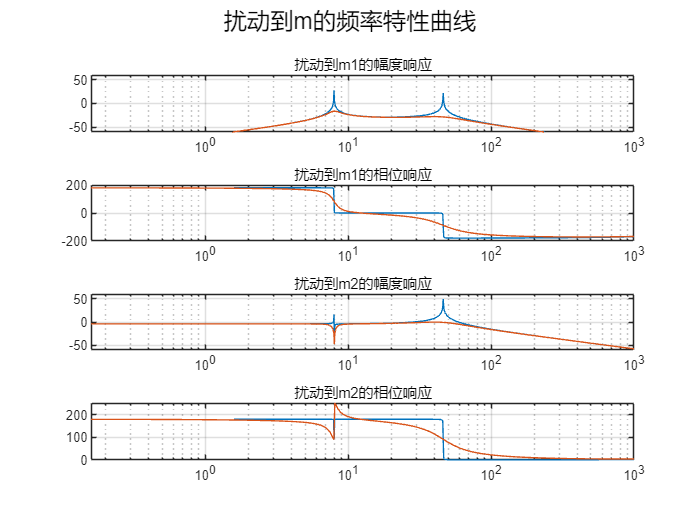

figure
[mag, phase, w] = bode(system); % 绘制伯德图
f = w ./ (2*pi);  % 将纵坐标转化为频率（赫兹）
sgtitle('扰动到m的频率特性曲线')
subplot(4, 1, 1);
semilogx(f, 20*log10(squeeze(mag(1,:,:))));  % 幅度响应（dB）
title('扰动到m1的幅度响应');
grid on % 显示网格
subplot(4, 1, 2);
semilogx(f, squeeze(phase(1,:,:)));  % 相位响应
title('扰动到m1的相位响应');
grid on % 显示网格
subplot(4, 1, 3);
semilogx(f, 20*log10(squeeze(mag(2,:,:))));  % 幅度响应（dB）
title('扰动到m2的幅度响应');
grid on % 显示网格
subplot(4, 1, 4);
semilogx(f, squeeze(phase(2,:,:)));  % 相位响应
title('扰动到m2的相位响应');
grid on % 显示网格
h = gcf; % 获取当前图形句柄
% 设置频率范围（以Hz为单位）
set(h.Children(1:4), 'XLim', [0, 1000]); % 频率范围
% 设置增益范围（以分贝为单位）
%set(h.Children(1), 'YLim', [-180, 45]); % 增益范围
set(h.Children(2), 'YLim', [-60, 60]); % 增益范围
%set(h.Children(3), 'YLim', [-360, 0]); % 增益范围
set(h.Children(4), 'YLim', [-60, 60]); % 增益范围

%% LQR伯德图绘制
[mag, phase, w] = bode(system_LQR); % 绘制伯德图
f = w ./ (2*pi);  % 将纵坐标转化为频率（赫兹）
sgtitle('扰动到m的频率特性曲线')

subplot(4, 1, 1);
hold on
semilogx(f, 20*log10(squeeze(mag(1,:,:))));  % 幅度响应（dB）
title('扰动到m1的幅度响应');
grid on % 显示网格
subplot(4, 1, 2);
hold on
semilogx(f, squeeze(phase(1,:,:)));  % 相位响应
title('扰动到m1的相位响应');
grid on % 显示网格
subplot(4, 1, 3);
hold on
semilogx(f, 20*log10(squeeze(mag(2,:,:))));  % 幅度响应（dB）
title('扰动到m2的幅度响应');
grid on % 显示网格
subplot(4, 1, 4);
hold on
semilogx(f, squeeze(phase(2,:,:)));  % 相位响应
title('扰动到m2的相位响应');
grid on % 显示网格
h = gcf; % 获取当前图形句柄
% 设置频率范围（以Hz为单位）
set(h.Children(2:5), 'XLim', [0, 1000]); % 频率范围
% 设置增益范围（以分贝为单位）
%set(h.Children(1), 'YLim', [-180, 45]); % 增益范围
set(h.Children(3), 'YLim', [-60, 60]); % 增益范围
%set(h.Children(3), 'YLim', [-360, 0]); % 增益范围
set(h.Children(5), 'YLim', [-60, 60]); % 增益范围